# Algorithmic Trading Project

## High Frequency Momentum Trading Stategy with Cryptocurrencies

Weihang Ren, April 20th 2020

## Data

Obtained from [CryptoCompare](http://cryptocompare.com) via their official [Python API](https://min-api.cryptocompare.com/documentation), the data consists of the **hourly** prices of 7 cryptocurrencies versus the US Dollar over three chosen stating dates until 14:00 on April 30th 2020:

- `2019-10-30 00:00` (6 months)

- `2019-04-30 00:00` (1 year)

- `2018-04-30 00:00` (2 years)

Select different time range `'TR'` to see visualization and results accordingly.

### Import data

% initialize
clear
% select time range: 6month, 1year or 2year
TR = "2y";

% config plots x limits
switch TR
    case "6m"
        xrange = [datetime(2019,10,29) datetime(2020,5,1)];
    case "1y"
        xrange = [datetime(2019,4,25) datetime(2020,5,1)];
    case "2y"
        xrange = [datetime(2018,4,25) datetime(2020,5,1)];
    otherwise
        warning('Unexpected plot range. No time selected.')
end

opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "Bitcoin", "Ethereum", "Ripple", "BitcoinCash", "Tether", "Litecoin", "EOS"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "time", "InputFormat", "yyyy-MM-dd HH:mm:ss");

% Import the data
crypto = readtimetable("data/crypto_"+TR+".csv", opts);

clear opts

### (TODO) Statistics summary

% head(crypto)
% corrplot(crypto);

### Plot price

f=figure;
f.Position(3)= 2*f.Position(3);

plot(crypto.time,crypto.Bitcoin,'DisplayName','crypto.Bitcoin');hold on;plot(crypto.time,crypto.Ethereum,'DisplayName','crypto.Ethereum');plot(crypto.time,crypto.Ripple,'DisplayName','crypto.Ripple');plot(crypto.time,crypto.BitcoinCash,'DisplayName','crypto.BitcoinCash');plot(crypto.time,crypto.Tether,'DisplayName','crypto.Tether');plot(crypto.time,crypto.Litecoin,'DisplayName','crypto.Litecoin');plot(crypto.time,crypto.EOS,'DisplayName','crypto.EOS');hold off;

legend({'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'},'Location','best')
ylabel('Price vs. USD')
xlim(xrange)

### Index price

We use indexed price to better capture the volatility across cryptocurrencies and use it to build our signal. Calculation reference: [this page](https://www.dallasfed.org/research/basics/indexing.aspx)


$$\hat{X}_t = \frac{X_t}{X_0}$$


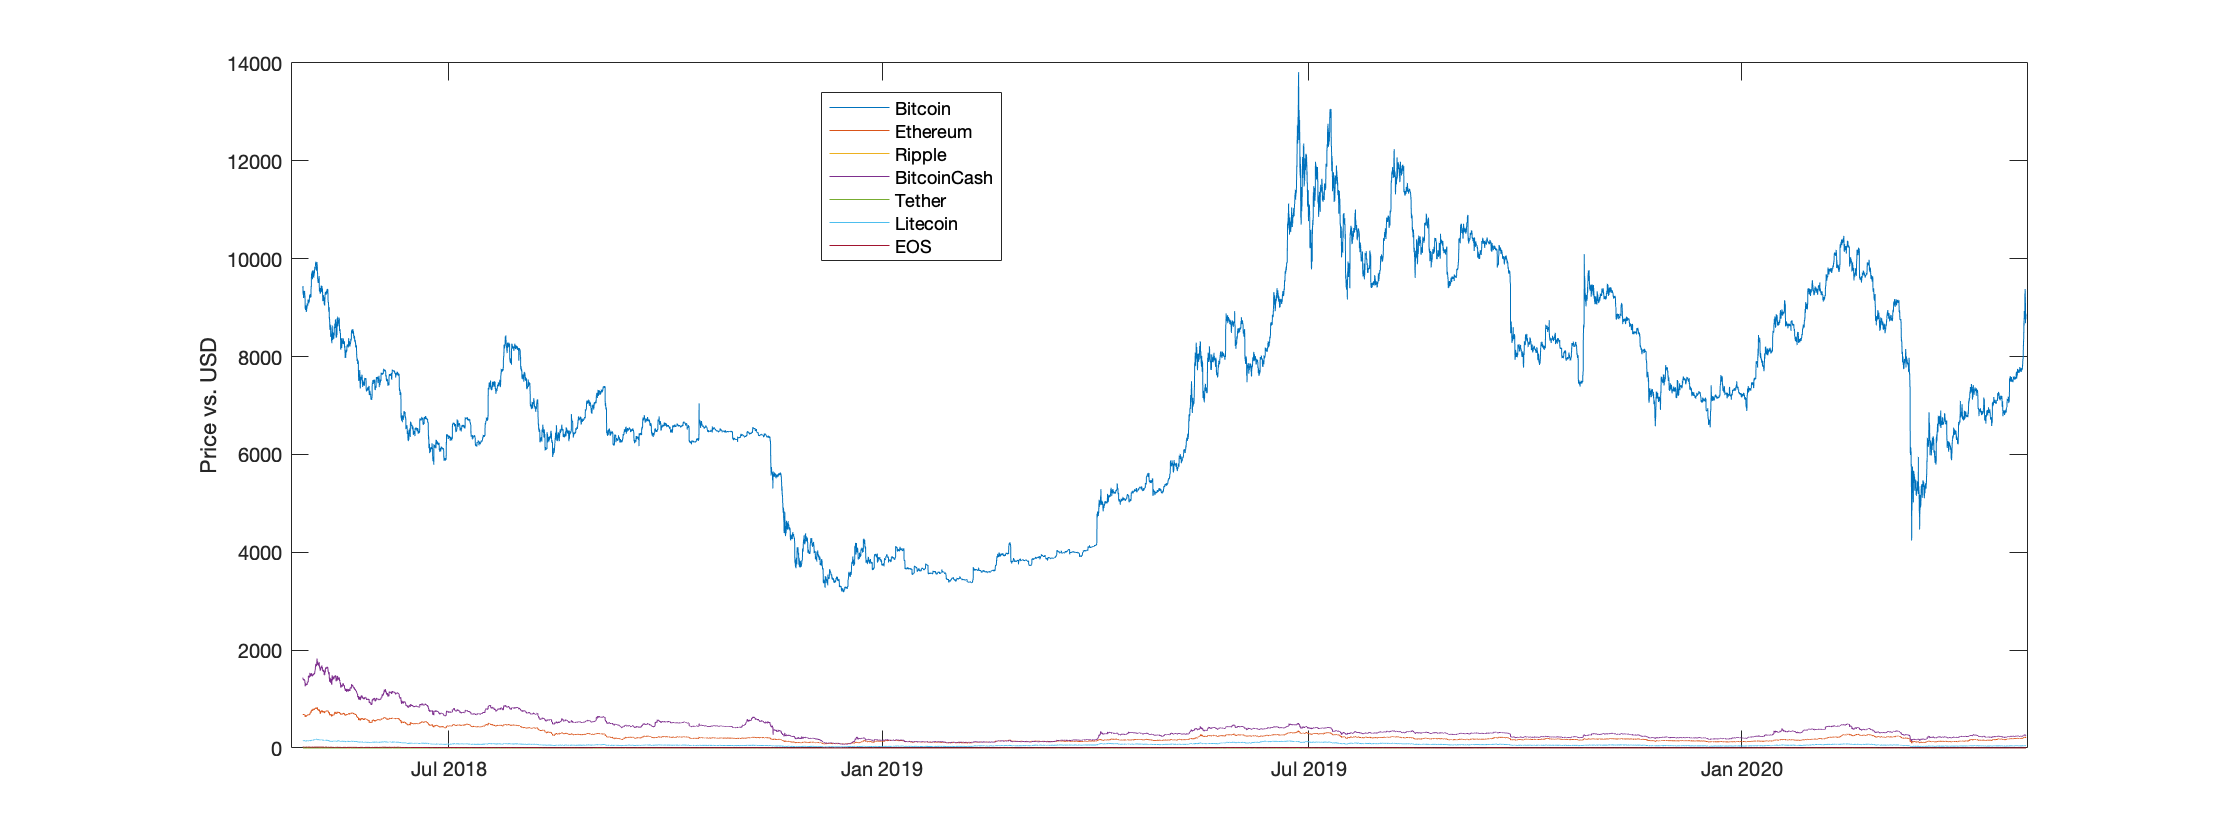

indexedPrice = crypto;
indexedPrice{2:end,:} = indexedPrice{2:end,:}./indexedPrice{1,:}*100;
indexedPrice{1,:} = 100;

#### Plot indexed price

plot(indexedPrice.time,indexedPrice.Bitcoin,'DisplayName','indexedPrice.Bitcoin');hold on;plot(indexedPrice.time,indexedPrice.Ethereum,'DisplayName','indexedPrice.Ethereum');plot(indexedPrice.time,indexedPrice.Ripple,'DisplayName','indexedPrice.Ripple');plot(indexedPrice.time,indexedPrice.BitcoinCash,'DisplayName','indexedPrice.BitcoinCash');plot(indexedPrice.time,indexedPrice.Tether,'DisplayName','indexedPrice.Tether');plot(indexedPrice.time,indexedPrice.Litecoin,'DisplayName','indexedPrice.Litecoin');plot(indexedPrice.time,indexedPrice.EOS,'DisplayName','indexedPrice.EOS');hold off;

legend({'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'},'Location','best')
ylabel('Indexed Price')
xlim(xrange)

[Tether](http://tether.to) is a stable coin.

## Method

### Exponential moving average

Ref: [Chu, 2020](https://doi.org/10.1016/j.ribaf.2019.101176).

$EMA_t(P,\alpha) = \alpha \cdot P_t+ (1-\alpha)EMA_{t-1}(P,\alpha)$ $(t>0)$, $EMA_0=P_0=1$,

where $P_t$ is the indexed exchange rate of a cryptocurrency at time $t$, and $\alpha = \frac{1}{n_k}$ is the exponential smoothing ratio.

Span/windowsize, alpha, half-life conversion see [pandas.ewm doc](https://pandas.pydata.org/pandas-docs/stable/reference/api/pandas.DataFrame.ewm.html).

% arbitrarily, n_k for short and long emas are [n_s, n_l] (days)
n = [8,24;16,48;32,96] 
% n = 2.*n-1; % span

It can often be seen that the exchange rates of cryptocurrencies show short bursts of upwards or downwards movements over the course of a few hours, and an EMA can capture this shorter term influence. 

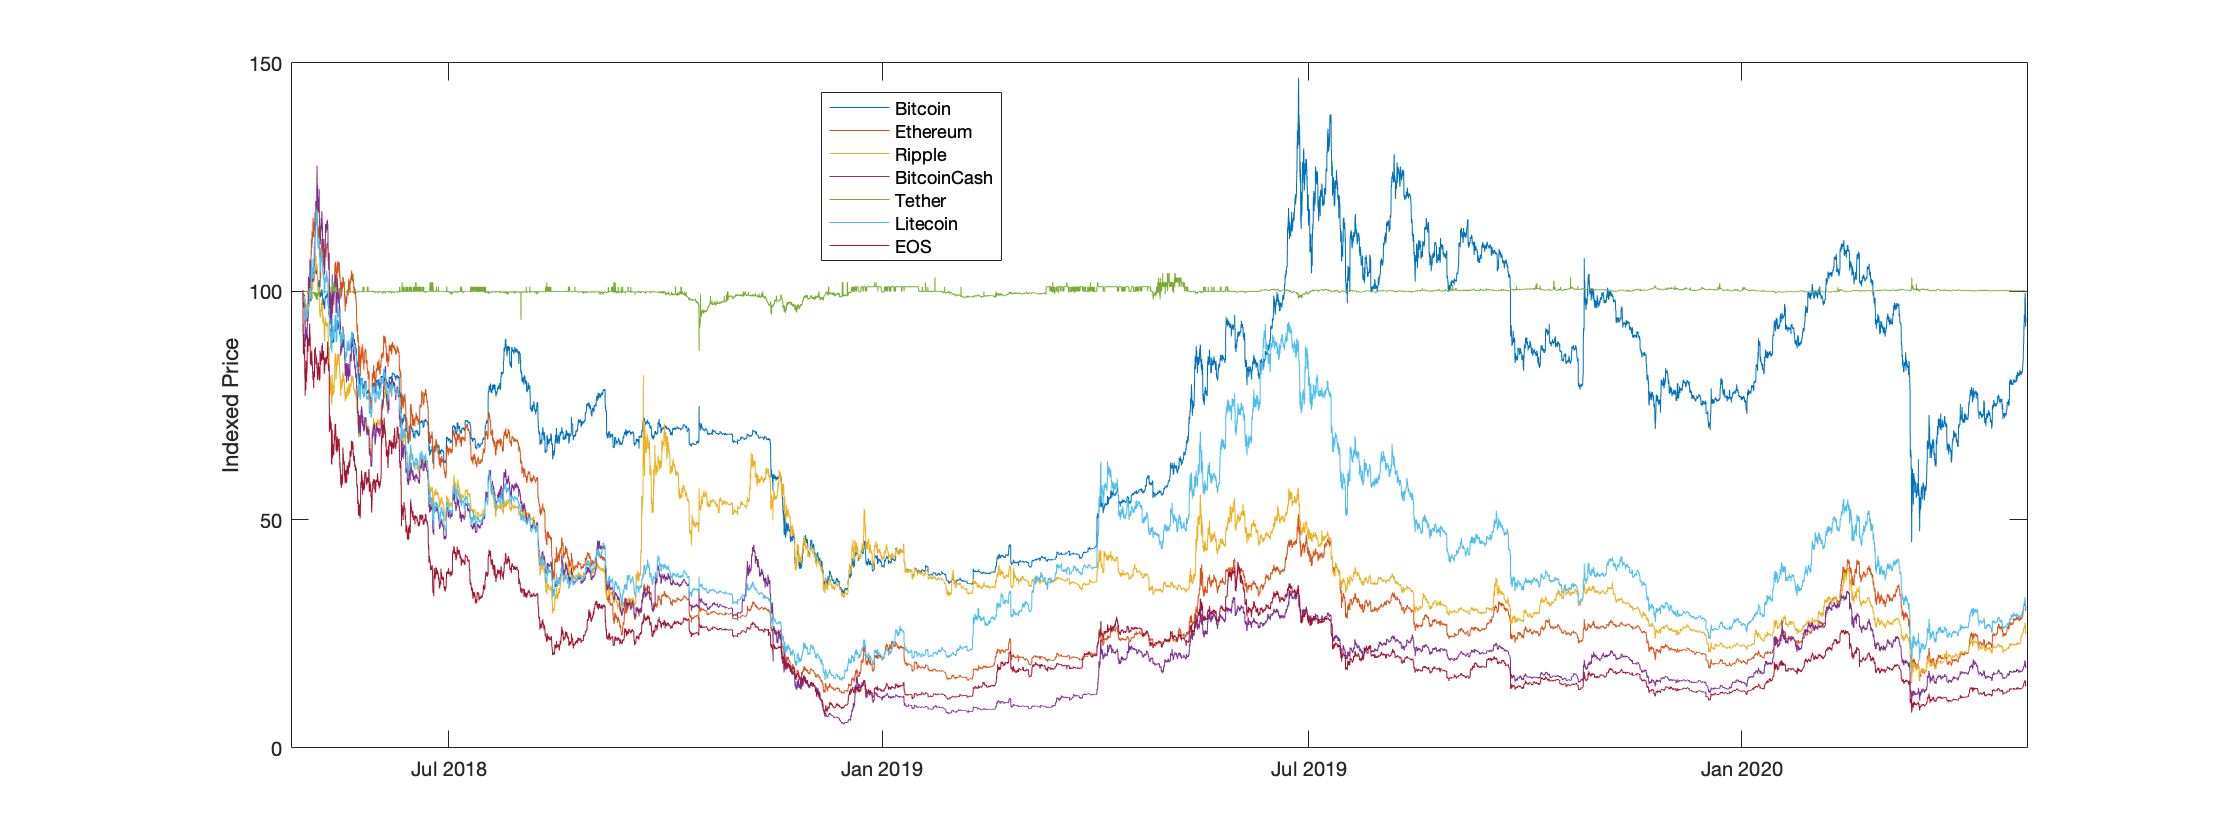

ema = indexedPrice;

type = 'exponential';
for i = 1:3
    for j = 1:2
        windowSize = round(n(i,j));
        ema(:,end+1:end+7) = movavg(ema(:,1:7),type,windowSize);
    end
end

% head(ema)


n =      8    24
    16    48
    32    96


bitcoinEma = ema(:,[1 8 15 22 29 36 43]);
bitcoinEma.Properties.VariableNames = {'Bitcoin' '8' '24' '16' '48' '32' '96'};
ethereumEma = ema(:,[2 9 16 23 30 37 44]);
ethereumEma.Properties.VariableNames = {'Ethereum' '8' '24' '16' '48' '32' '96'};
rippleEma = ema(:,[3 10 17 24 31 38 45]);
rippleEma.Properties.VariableNames = {'Ripple' '8' '24' '16' '48' '32' '96'};
bitcoincashEma = ema(:,[4 11 18 25 32 39 46]);
bitcoincashEma.Properties.VariableNames = {'BitcoinCash' '8' '24' '16' '48' '32' '96'};
tetherEma = ema(:,[5    12    19    26    33    40    47]);
tetherEma.Properties.VariableNames = {'Tether' '8' '24' '16' '48' '32' '96'};
litecoinEma = ema(:,[6    13    20    27    34    41    48]);
litecoinEma.Properties.VariableNames = {'Litecoin' '8' '24' '16' '48' '32' '96'};
eosEma = ema(:,[7    14    21    28    35    42    49]);
eosEma.Properties.VariableNames = {'EOS' '8' '24' '16' '48' '32' '96'};

#### Visualization

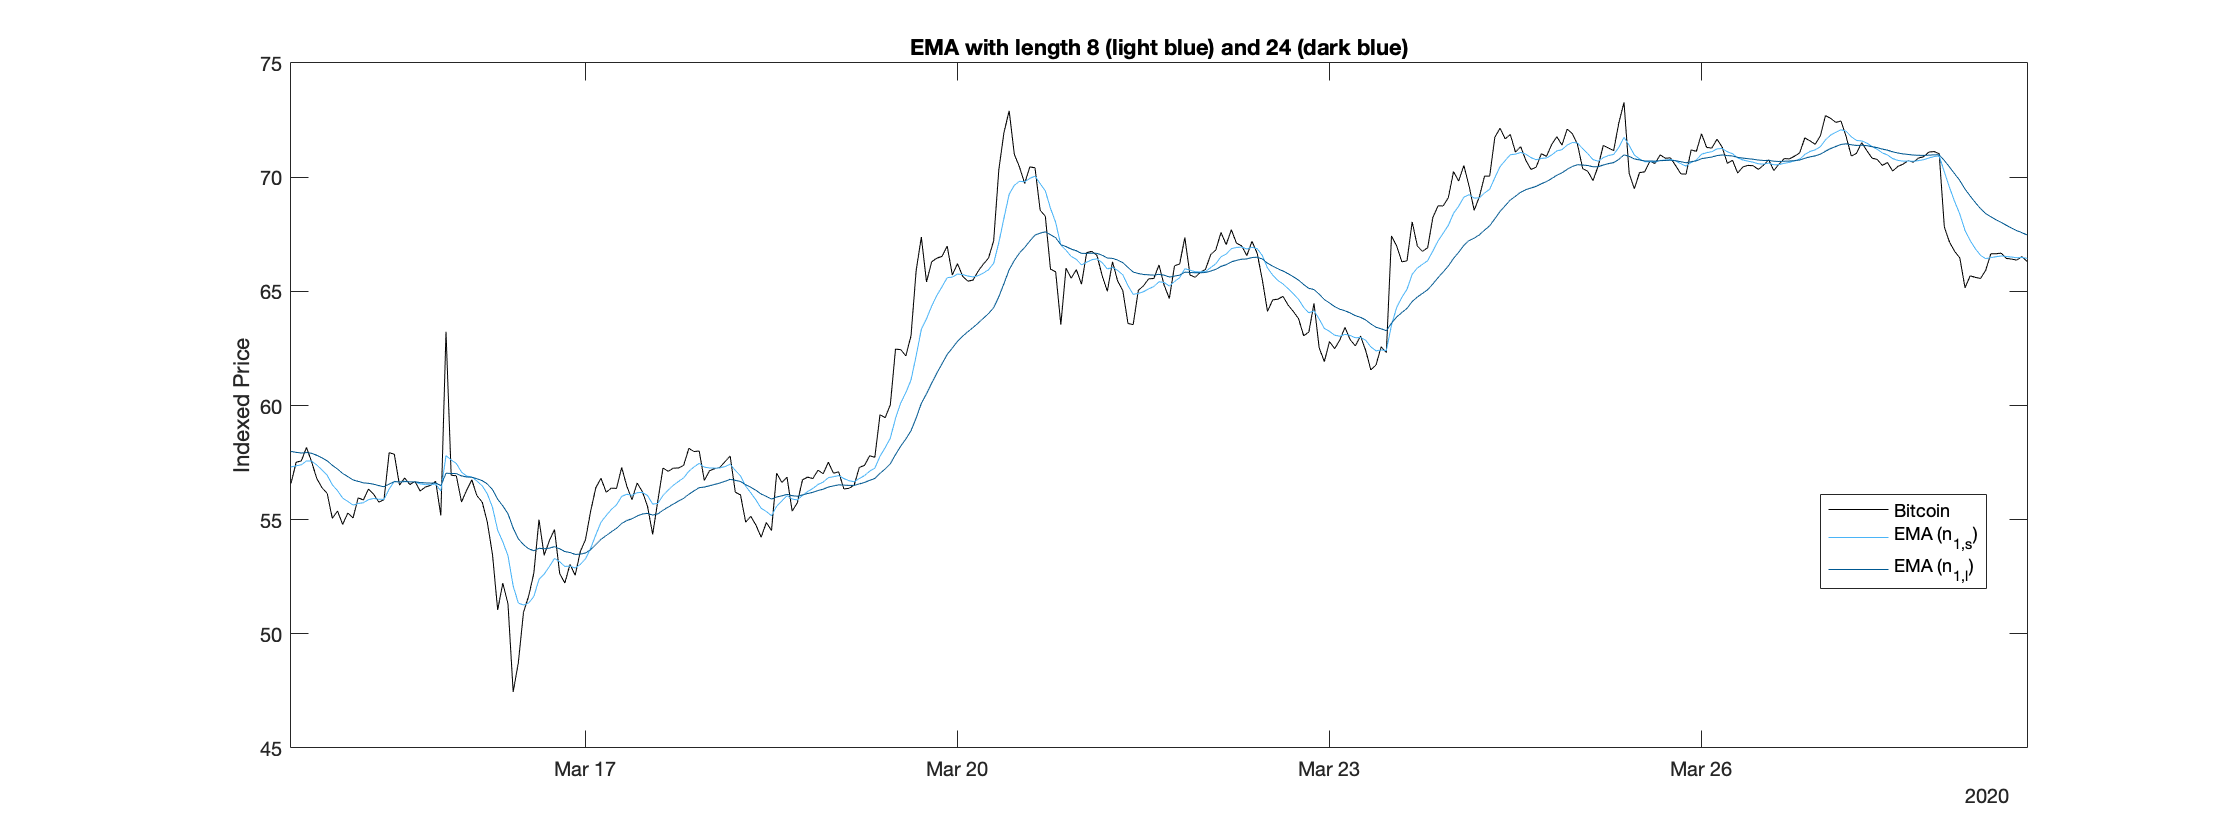

% change the symbol to see other crypto
symbol = bitcoinEma;
% change the datetime span to adjust plots horizon
span = [datetime(2020,3,14,15,0,0) datetime(2020,3,28,15,0,0)];


name = symbol.Properties.VariableNames(1);
name = string(name);

% plot n1
plot(symbol.time,symbol.(name),'k','DisplayName','bitcoinEma.Bitcoin');hold on;plot(symbol.time,symbol.(2),'Color','#4ab4f7','DisplayName','bitcoinEma.(3)');plot(symbol.time,symbol.(3),'Color','#005891','DisplayName','bitcoinEma.(4)');hold off;

xlim(span)
legend({name,'EMA (n_{1,s})','EMA (n_{1,l})'},'Location','best')
title('EMA with length 8 (light blue) and 24 (dark blue)')
ylabel('Indexed Price')

% plot n2
plot(symbol.time,symbol.(name),'k','DisplayName','bitcoinEma.Bitcoin');hold on;plot(symbol.time,symbol.(4),'Color','#97db3b','DisplayName','bitcoinEma.(3)');plot(symbol.time,symbol.(5),'Color','#4c8203','DisplayName','bitcoinEma.(4)');hold off;

xlim(span)
legend({name,'EMA (n_{2,s})','EMA (n_{2,l})'},'Location','best')
title('EMA with length 16 (light green) and 48 (dark green)')
ylabel('Indexed Price')

% plot n3
plot(symbol.time,symbol.(name),'k','DisplayName','bitcoinEma.Bitcoin');hold on;plot(symbol.time,symbol.(6),'Color','#eb7389','DisplayName','bitcoinEma.(3)');plot(symbol.time,symbol.(7),'Color','#A2142F','DisplayName','bitcoinEma.(4)');hold off;

xlim(span)
legend({name,'EMA (n_{3,s})','EMA (n_{3,l})'},'Location','best')
title('EMA with length 32 (light red) and 96 (dark red)')

ylabel('Indexed Price')

### Base signal for momentum strategy

Its sign determines whether one goes long or short in this currency. 


$$x_k = EMA\left(P,\frac{1}{n_{k,s}}\right) - EMA\left(P,\frac{1}{n_{k,l}}\right) $$


The values of $x_k$ is

- positive: positive trend

- negative: negative trend

- equal to zero: the two EMAs intersect, trend changes direction.

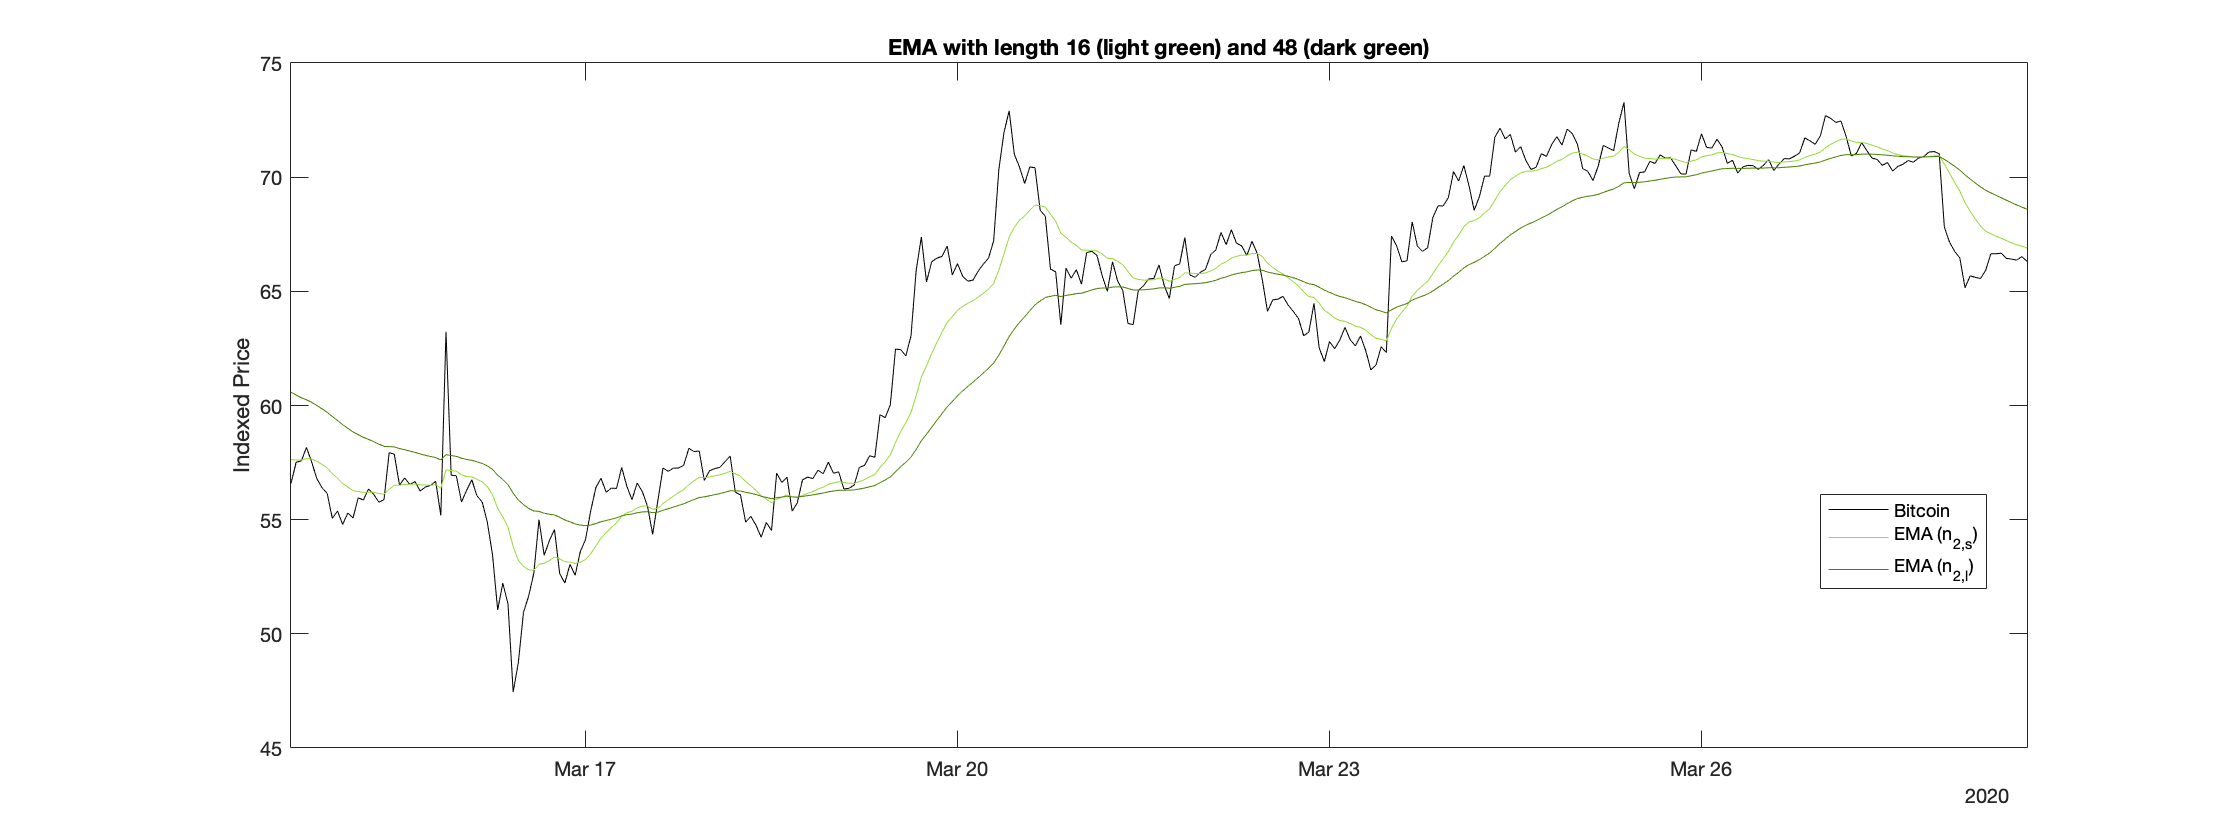

% calculate base signal
baseSignal = timetable(symbol.time, symbol.(2)-symbol.(3),symbol.(4)-symbol.(5),symbol.(6)-symbol.(7),'VariableNames',{'x1' 'x2' 'x3'});

% plot
figure;
plot(baseSignal.Time,baseSignal.x1,'Color','#005891','DisplayName','baseSignal.x1');hold on;plot(baseSignal.Time,baseSignal.x2,'Color','#4c8203','DisplayName','baseSignal.x2');plot(baseSignal.Time,baseSignal.x3,'Color','#A2142F','DisplayName','baseSignal.x3');hold off;
hline(0,'k:');

xlim(span)
legend({'x_1','x_2','x_3'},'Location','best')
title('Base signal of '+name)
ylabel('x_k')

% correlation between x_k
corrplot(baseSignal);

Reducing the correlation leads to a longer time window, and vice versa. 

(TODO:) One can optimize the $n_k$ for each currency, but the risk of **overfitting** must be considered. 

#### Two-step normalization

We use time frames of 168 h or one week (short) rolling standard deviations, and 1440 h or two month (long) rolling standard deviations with a 20% hold-out.

$y_k = \frac{x_k}{\sigma_{168}(P)}$,   $z_k = \frac{y_k}{\sigma_{1440}(P)}$

First transformation lowers high volatitly and amplifies low volatility. The second's effect is similar.

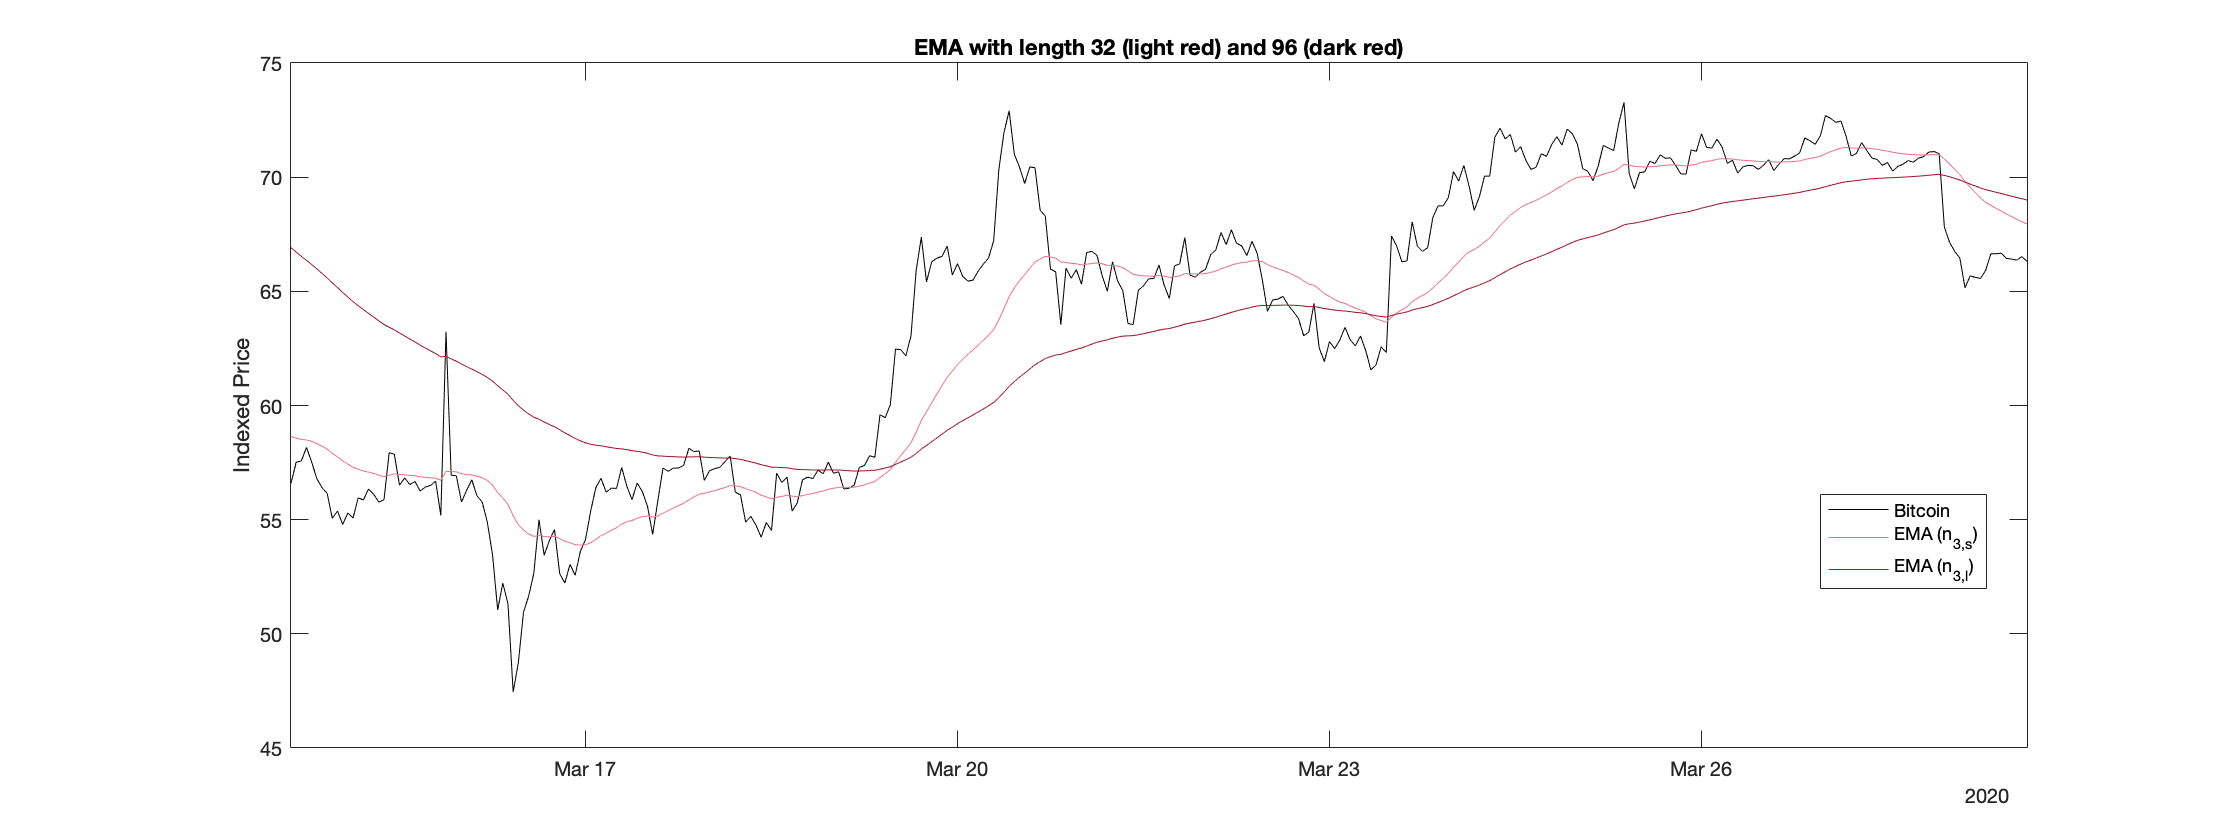

norm = baseSignal;

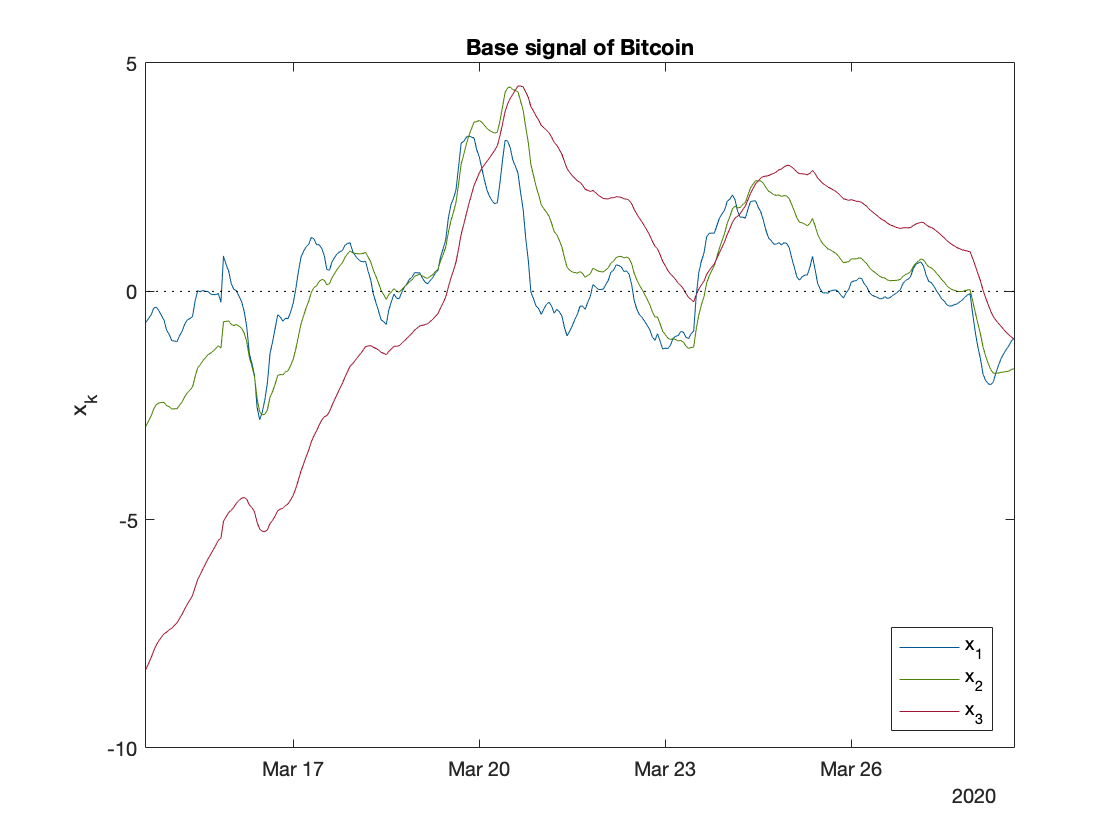

shortStd = movstd(norm.Variables,[134 33]);  % 168  = 134  +1 +33
longStd = movstd(norm.Variables,[1152 287]); % 1440 = 1152 +1 +287

yBaseSignal = norm.Variables./shortStd;
zBaseSignal = yBaseSignal./longStd;
norm(:,["y1" "y2" "y3"]) = array2table(yBaseSignal);
norm(:,["z1" "z2" "z3"]) = array2table(zBaseSignal);
norm(:,["std_s1" "std_s2" "std_s3"]) = array2table(shortStd);
norm(:,["std_l1" "std_l2" "std_l3"]) = array2table(longStd);

% plot effect of normalization
figure;
subplot(2,1,1);
plot(norm.Time,norm.std_s1,'k')
xlim(span)
legend({'\sigma_{168(P)}'},'Location','best')

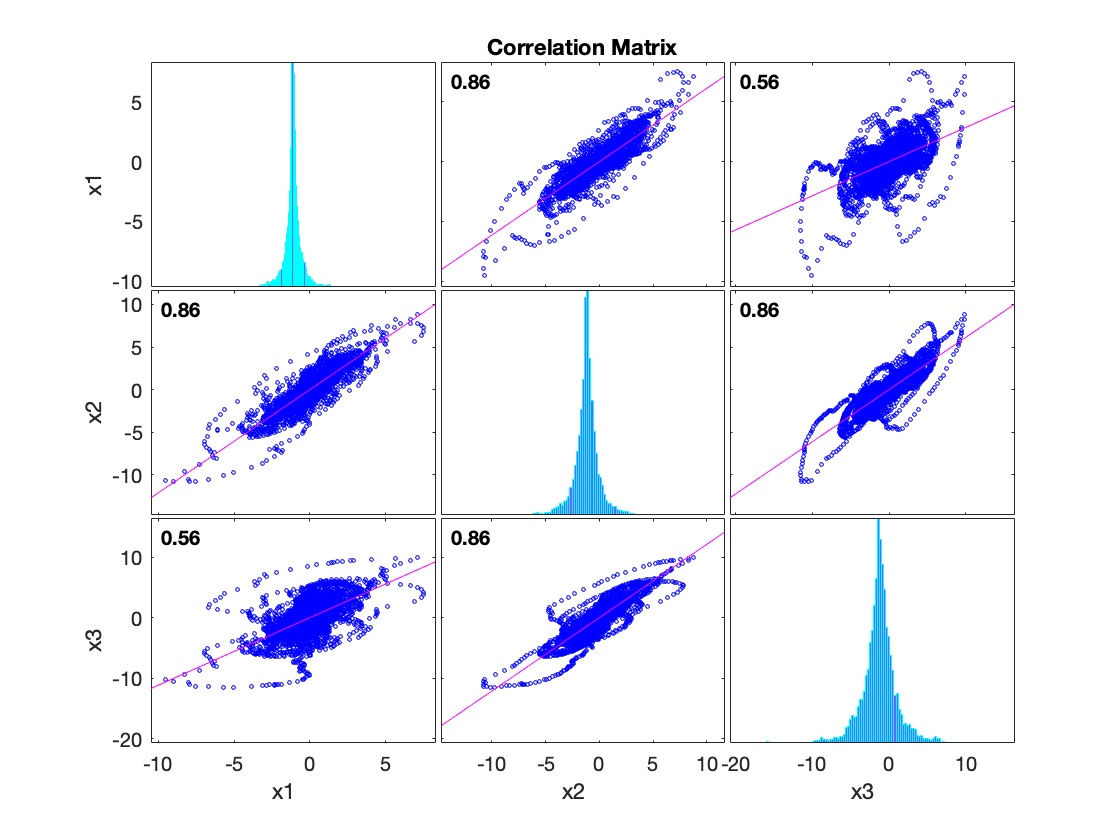

title('Effect of the normalization')
ylabel('Standard deviation')
subplot(2,1,2);

plot(norm.Time,norm.x1,'DisplayName','norm.x1');hold on;plot(norm.Time,norm.y1,'DisplayName','norm.y1');hold off;
xlim(span)
hline(0,'k:');
legend({'x_1','y_1'},'Location','best')
ylabel('x_1, y_1');

% plot z_k
figure;
plot(norm.Time,norm.z1,'Color','#005891','DisplayName','norm.z1');hold on;plot(norm.Time,norm.z2,'Color','#4c8203','DisplayName','norm.z2');plot(norm.Time,norm.z3,'Color','#A2142F','DisplayName','norm.z3');hold off;
hline(0,'k:');
xlim(span)
legend({'z_1','z_2','z_3'},'Location','best')
title('Normalized signal of '+name)
ylabel('z_k')

#### Generate signal

To scale $z_k$ between -1 and 1, we use **response function** proposed by [Rohrbach et al. (2017)](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=2949379), which used geometric Brownian Motion.


$$u_k (z_k) = \frac{z_k\cdot e^{-z_k^2/4}}{\sqrt{2}\cdot e^{-1/2}}$$


z = linspace(-10,10);
u = (z.*exp(-z.^2/4)) / (sqrt(2)*exp(-1/2));
figure;
plot(z,u);
xlim([-11 11])
ylim([-1.1 1.1])
hline(1,'k:');
hline(-1,'k:');
title('Response function')
xlabel('z_k')
ylabel('u_k')

z_k = norm{:,["z1" "z2" "z3"]};
u_k = (z_k.*exp(-z_k.^2/4)) / (sqrt(2)*exp(-1/2));

Final signal is calculated as


$$Signal = \sum_{k=1}^3w_ku_k$$


with equal weighted $w_k=1/3$.

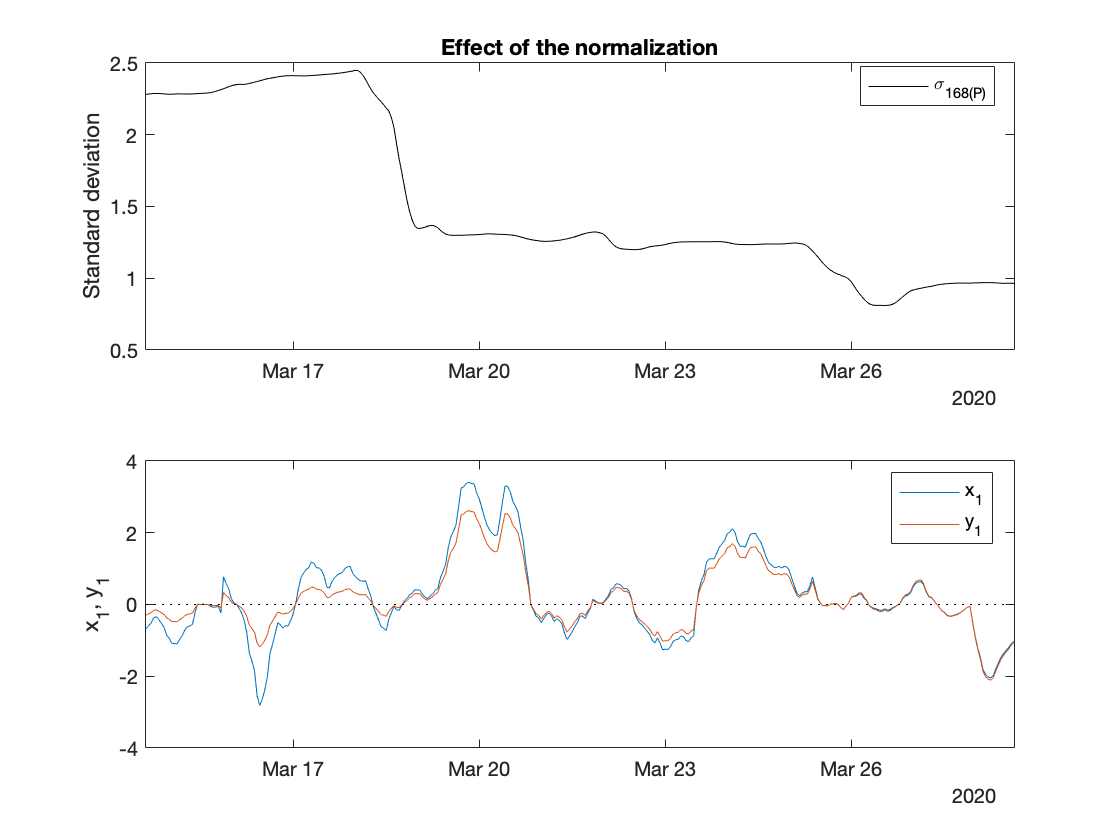

signal = timetable(norm.Properties.RowTimes,mean(u_k,2));
signal.Properties.VariableNames = {'Signal'};
plot(signal.Time,signal.Signal);

xlim(span);
hline(0,'k:');
ylabel('Signal');
title('Signal of '+name);

**Create signal for all cryptos**

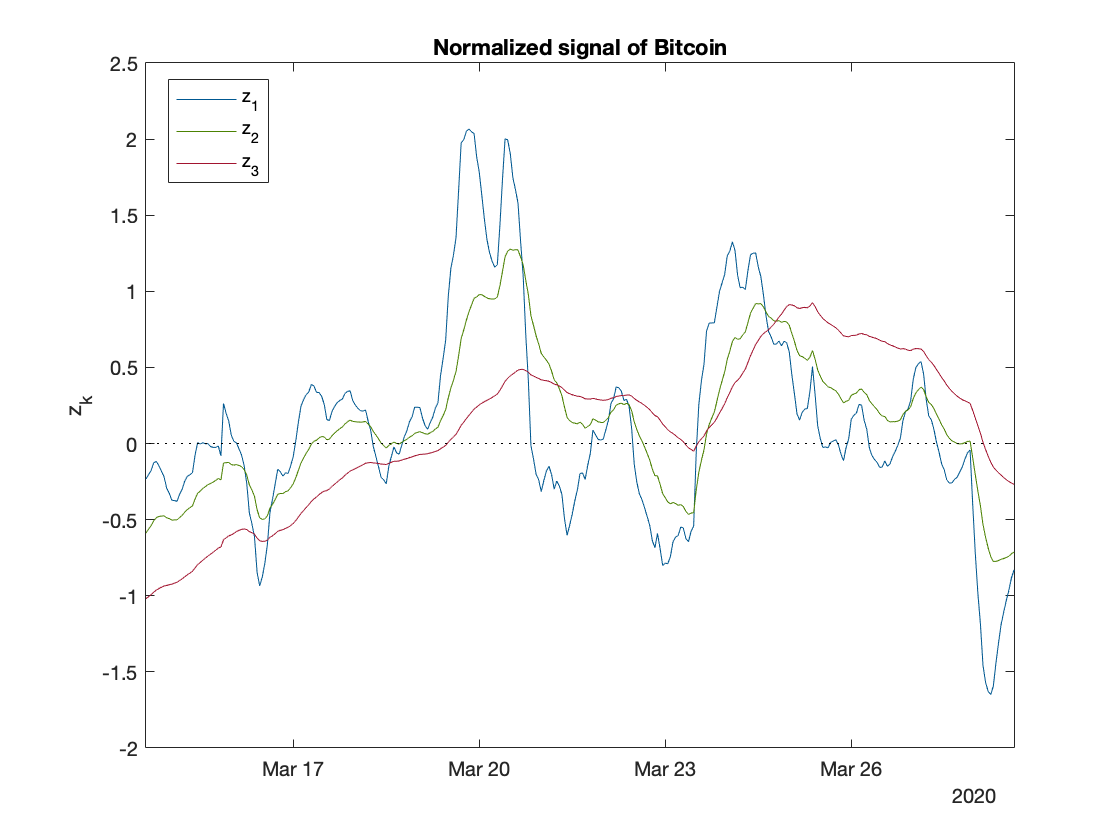

symbolsEma = {bitcoinEma,ethereumEma,rippleEma,bitcoincashEma,tetherEma,litecoinEma,eosEma};

% table of signals
signalT = genRohrbachSignal(symbolsEma);
head(signalT)

## Portfolio types

We find only Tether has weak correlationwith other cryptos' returns.

[rtn, intv] = tick2ret(crypto,'Method','Continuous'); % first timestamp dropped

% correlation
corrplot(rtn)
title('Correlations between the log returns of cryptocurrencies');

### Times series port

Rebalancing every hour: buy (or sell) **1/n of the signal** units of US dollars for a cryptocurrency. n=7.


$$tsReturn_t = Signal_{t-1}\times \frac{1}{7}\times\frac{1}{P_{t-1} }\times R_t$$


where $1/P_{t-1}$ coincide with the indexed exchange rate of USD/crypto at signal period, $R_t$ is the log return of indexed price at time $t$.

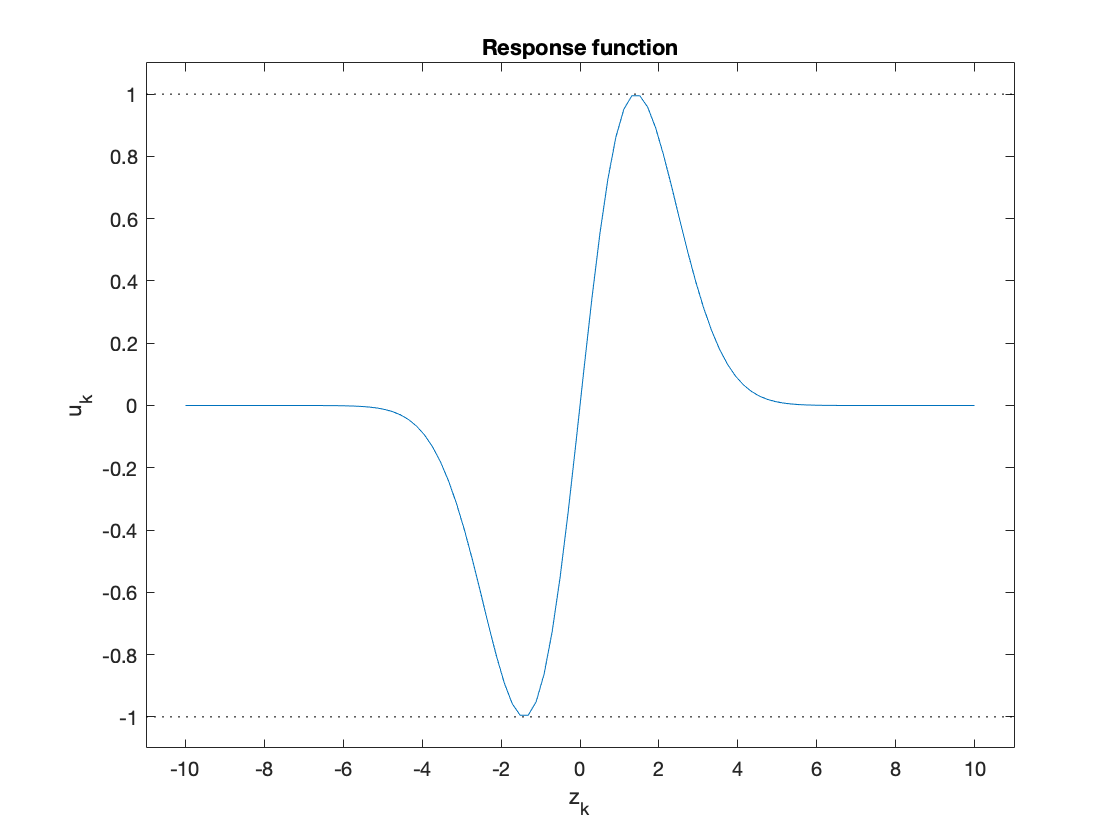

tsPort = signalT{:,:} ./7 ./crypto{:,:}; % cryptos
tsPort = array2table(tsPort,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});
tsPort = table2timetable(tsPort,"RowTimes",signalT.Properties.RowTimes);

tsRtn = tsPort{1:end-1,:} .* rtn{:,:};
tsRtn = array2table(tsRtn,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});

tsRtn = table2timetable(tsRtn,"RowTimes",signalT.Properties.RowTimes(1:end-1));

### Cross-sectional port

Each hour, we long the three cryptocurrencies with the largest signals, and short three with the most negative signals. These 6 trades are equally weighted in USD.


$$csReturn_t = \pm \frac{1}{6}\times\frac{1}{P_{t-1} }\times R_t$$


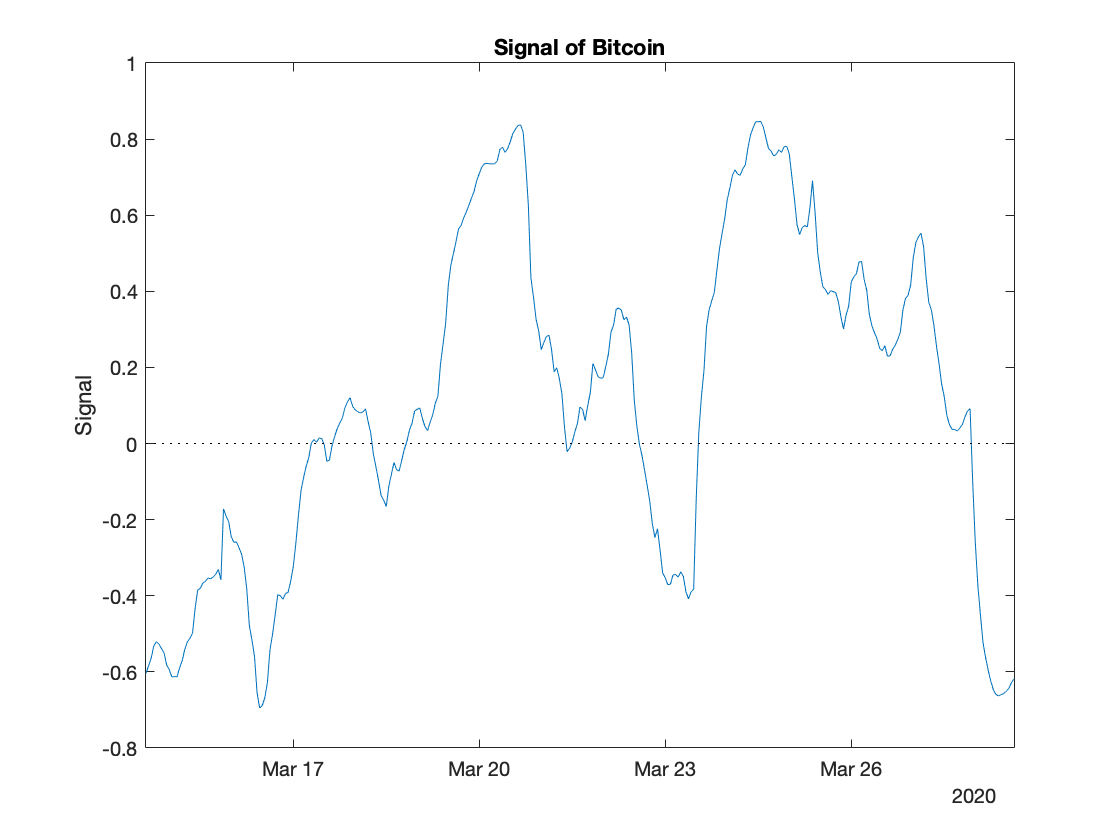

[B,posIdx] = maxk(signalT{:,:},3,2);
filterSignalT = signalT{:,:};
[C,negIdx] = mink(signalT{:,:},3,2);
for i = 2:length(filterSignalT)
    filterSignalT(i,posIdx(i,:)) =  1;
    filterSignalT(i,negIdx(i,:)) = -1;
end
filterSignalT((filterSignalT~=1) & (filterSignalT~=-1)) = 0;

csPort = filterSignalT(:,:) ./6 ./crypto{:,:};
csPort = array2table(csPort,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});
csPort = table2timetable(csPort,"RowTimes",signalT.Properties.RowTimes);


csRtn = csPort{1:end-1,:} .* rtn{:,:};
csRtn = array2table(csRtn,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});
csRtn = table2timetable(csRtn,"RowTimes",signalT.Properties.RowTimes(1:end-1));

### Benchmark

Equally weighted investment.

bmPort = 1 /7 ./crypto{:,:};
bmPort = array2table(bmPort,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});

ans = 8×7 timetable
           Time            Bitcoin     Ethereum     Ripple     BitcoinCash      Tether       Litecoin       EOS   
    ___________________    ________    ________    ________    ___________    __________    __________    ________

    2018-04-30 01:00:00           0           0           0             0              0             0           0
    2018-04-30 02:00:00    0.072081    0.016584    0.026314      0.012803     1.0517e-10    -0.0028991    -0.12353
    2018-04-30 03:00:00    -0.22695    -0.14274    -0.15496     -0.077223     2.1009e-10      -0.20842    -0.38591
    2018-04-30 04:00:00     -0.4338    -0.23099    -0.21709     

bmPort = table2timetable(bmPort,"RowTimes",signalT.Properties.RowTimes);

bmRtn = rtn{:,:} .* bmPort{1:end-1,:};
bmRtn = array2table(bmRtn,'VariableNames',{'Bitcoin','Ethereum','Ripple','BitcoinCash','Tether','Litecoin','EOS'});
bmRtn = table2timetable(bmRtn,"RowTimes",signalT.Properties.RowTimes(1:end-1));

### Transaction Cost

([Lintilhac 2017](https://doi-org.ezproxy.cul.columbia.edu/10.1080/14697688.2016.1231928)) (Platanakis 2019)

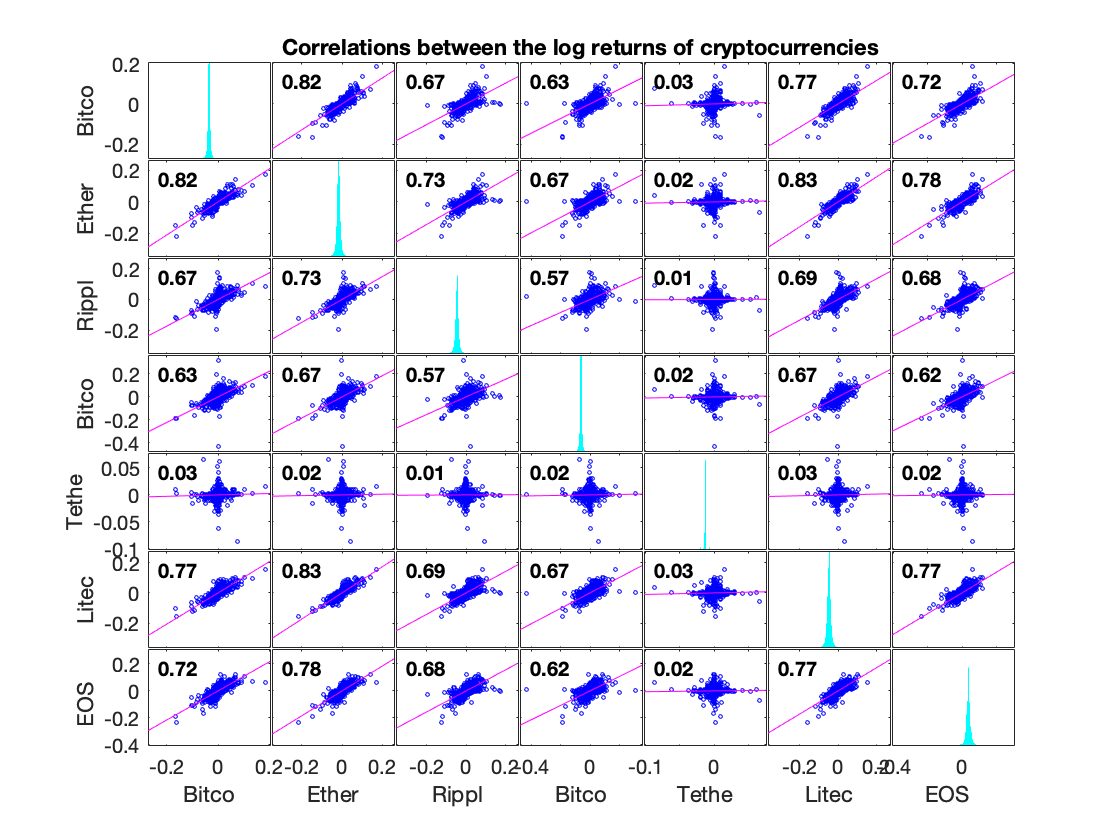

riskFreeRate      =   0.01/252; % PERCENT PER DAY
managementFeeRate =   0.01/252; % PERCENT PER DAY

**(TODO) Market impact**

Reorder colors. (Original third color yellow was hard to distinguish from the second color orange).

newcolors = [0 0.4470 0.7410
             0.8500 0.3250 0.0980
             0.4660 0.6740 0.1880];
         
colororder(newcolors)

## Performance Analysis

### Returns

tsTotalRtn = sum(tsRtn{:,:},2);
csTotalRtn = sum(csRtn{:,:},2);
bmTotalRtn = sum(bmRtn{:,:},2);

% plot
f=figure;
f.Position(3)= 2*f.Position(3);
plot(indexedPrice.time(1:end-1),[bmTotalRtn csTotalRtn tsTotalRtn])
title('Daily returns');
legend({'Benchmark','Cross-sectional','Time series'},'Location','best');
ylabel('Return');
xlim(xrange)

% histogram
histogram(bmTotalRtn); hold on;
histogram(csTotalRtn); hold on;
histogram(tsTotalRtn);
set(gca, 'YScale', 'log'); 
xlabel('Return');
ylabel('# Observations [log scale]');
title('Portfolio Returns');
legend({'Benchmark','Cross-sectional','Time series'},'Location','best');
grid on
% vline(0,'k-')
xlim([-5e-2 5e-2])
hold off;

### Equity

**Cross-sectional** portfolio obtained highest cumulative return (without transaction cost) before April 2020.

% without transaction cost
tsCumRtn = cumsum(tsTotalRtn(:,:));
csCumRtn = cumsum(csTotalRtn(:,:));
bmCumRtn = cumsum(bmTotalRtn(:,:));

% plot
plot(indexedPrice.time(1:end-1),[bmCumRtn csCumRtn tsCumRtn])
grid on
hline(0,'k-');
vline(datetime(2020,4,1),'k-');
title('Portfolio returns without transaction fees');
legend({'Benchmark','Cross-sectional','Time series'},'Location','best');
ylabel('Cumulative return');
xlim(xrange)

% with transaction cost


### Drawdowns

"A drawdown is a peak-to-trough decline during a specific period for an investment, trading account, or fund. A drawdown is usually quoted as the percentage between the peak and the subsequent trough." ([Investopedia](https://www.investopedia.com/terms/d/drawdown.asp)) 

We can see **cross-sectional** portfolio has least drawdown due to the COVID-19.

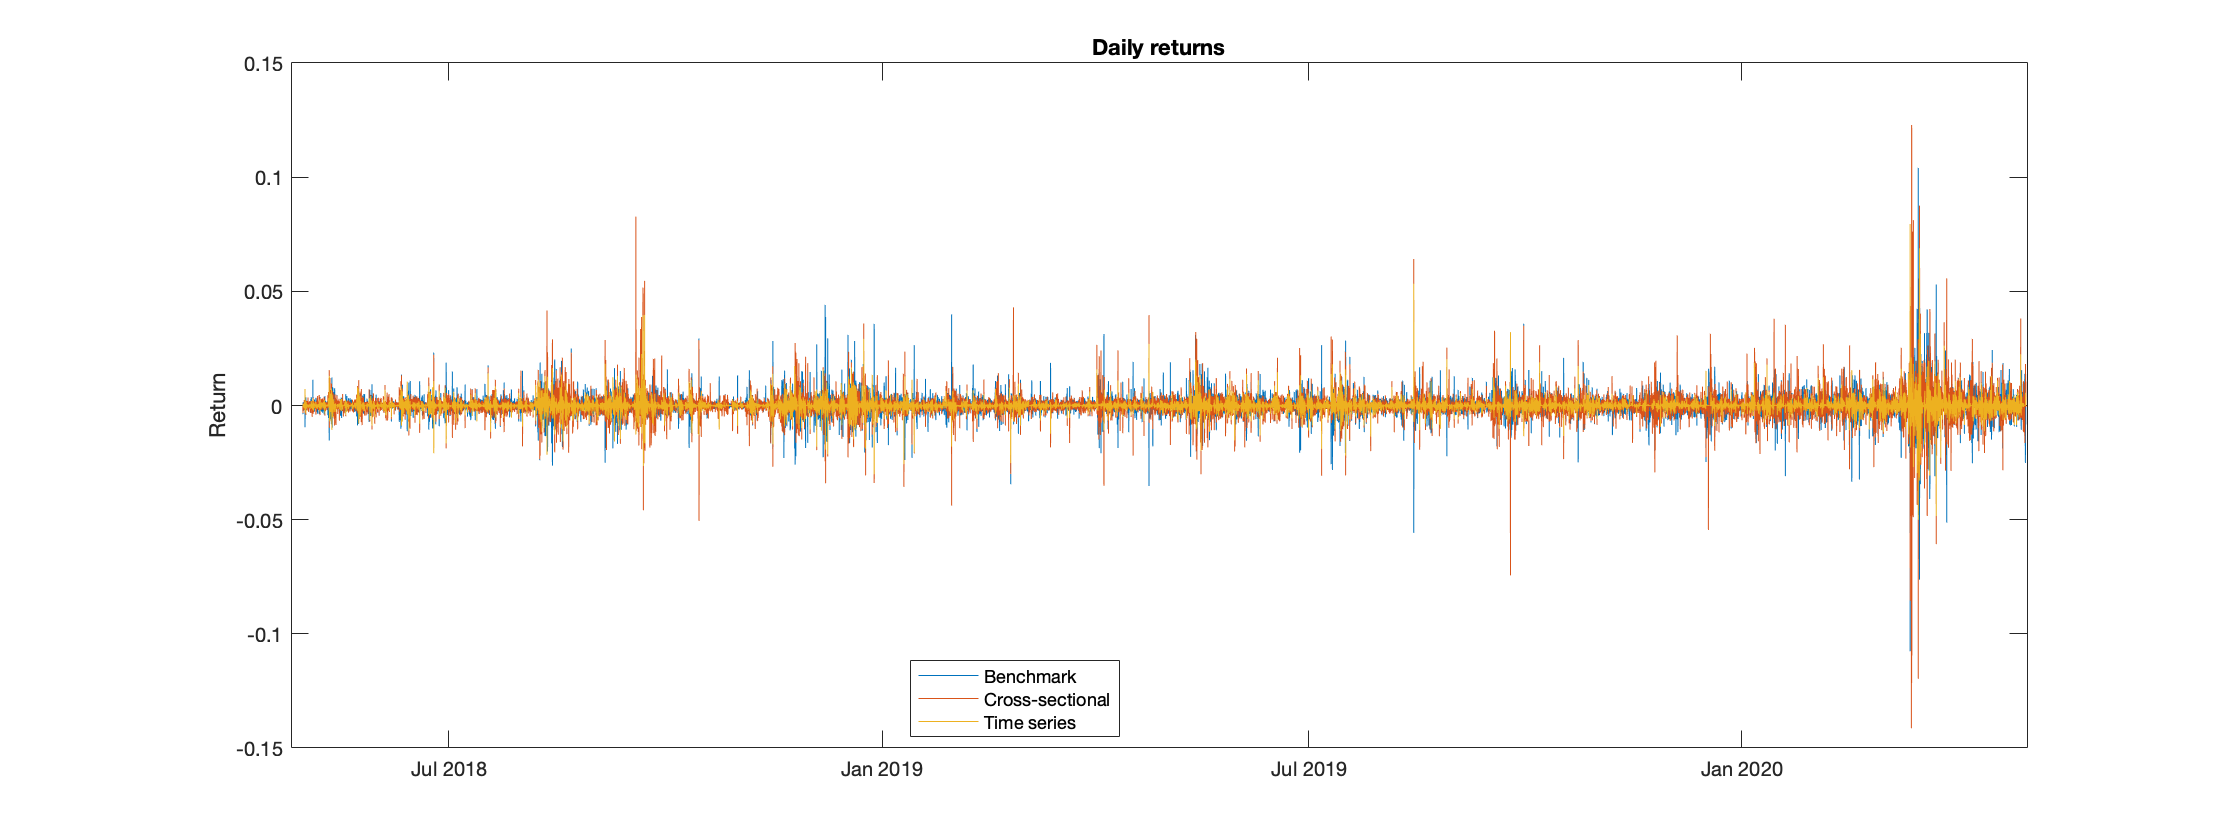

names = {'Benchmark','Cross-sectional','Time series'};
tsDD = 100.*-calculateDD(tsTotalRtn);
csDD = 100.*-calculateDD(csTotalRtn);
bmDD = 100.*-calculateDD(bmTotalRtn);

plot(rtn.time,[bmDD csDD tsDD]);
vline(datetime(2020,4,1),'k-');
ylabel('Drawdown');
ytickformat('%5.0f%%');
legend(strrep(names,'_',' '),'location','best');
grid on
xlim(xrange)

### Performance summary

retns = table(bmTotalRtn,csTotalRtn,tsTotalRtn);
summaryPerformance(retns,riskFreeRate)

## Discussion and future work

### **Discussion**

Strengths:

- Cross-sectional portfolio has the highest Sharpe ratio

- Time series portfolio performs better when not in crisis

Weakness:

- No single strategy beats others the whole time

- Long term Sharpe raios are small

- Asset selection is fixed

### Future work

- **Data**: use TAQ data

- **Model**: Determine the mechanics set two strategies apart during crisis

- **Backtesting**: Take more specific transaction cost and market impact into account

## Reference

- Chu J, Chan S, Zhang Y. (2020) High frequency momentum trading with cryptocurrencies. *Research in international business and finance*. 52:101176.

- Rohrbach, Janick and Suremann, Silvan and Osterrieder, Joerg (2017) Momentum and Trend Following Trading Strategies for Currencies and Bitcoin. *Combining Academia and Industry.* 

- P. S. Lintilhac & A. Tourin (2017) Model-based pairs trading in the bitcoin markets. *Quantitative Finance.* 17:5, 703-716.

- Platanakis, Emmanouil & Urquhart, Andrew (2019) Portfolio management with cryptocurrencies: The role of estimation risk. *Economics Letters*. ISSN: 0165-1765, Volume 177, p. 76.

## Local Functions

No need to include this part in slides.

### Rohrbach Signal

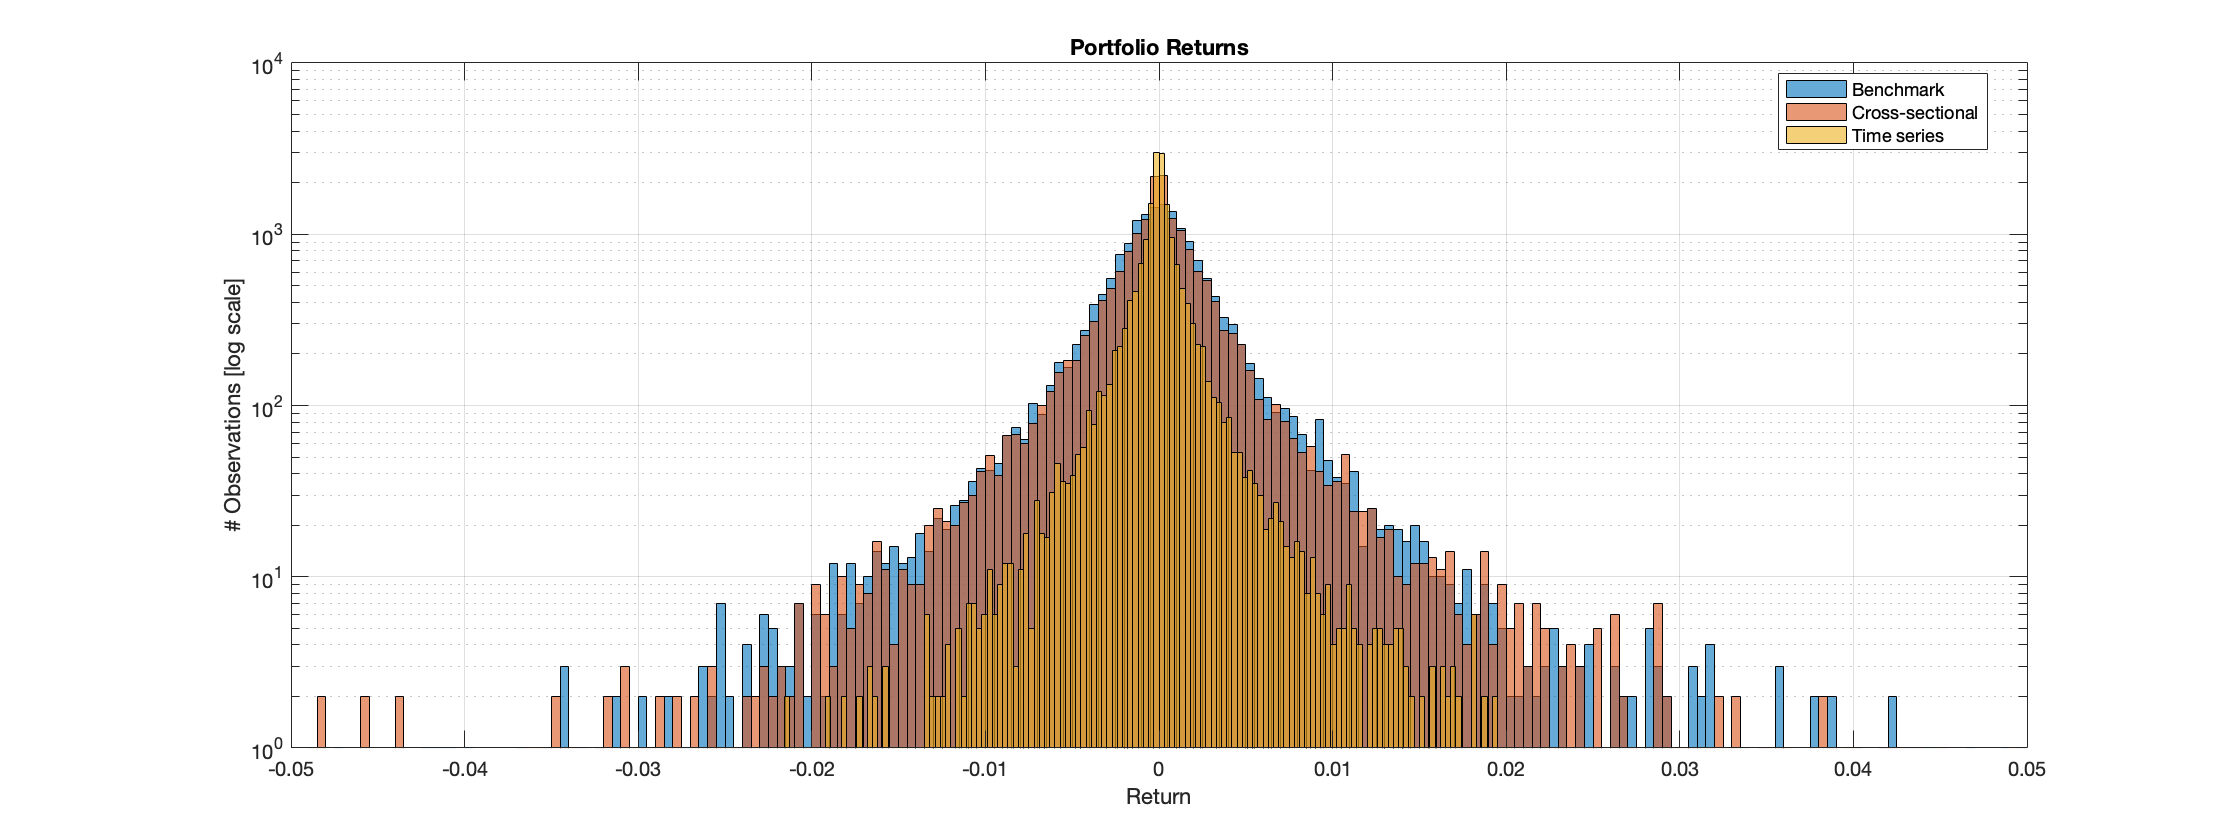

function rohrbachSignal = genRohrbachSignal(symbolsEma)
    for i = 1:length(symbolsEma)
        symbol = symbolsEma{i};
        tick = symbol.Properties.VariableNames(1);
        tick = string(tick);
        baseSignal = timetable(symbol.time, symbol.(2)-symbol.(3),symbol.(4)-symbol.(5),symbol.(6)-symbol.(7),'VariableNames',{'x1' 'x2' 'x3'});
        
        shortStd = movstd(baseSignal.Variables,[134 33]);  % 168  = 134  +1 +33
        longStd = movstd(baseSignal.Variables,[1152 287]); % 1440 = 1152 +1 +287
        y = baseSignal.Variables./shortStd;

        z = y./longStd;
        u = (z.*exp(-z.^2/4)) / (sqrt(2)*exp(-1/2));
        
        signal = timetable(baseSignal.Properties.RowTimes,mean(u,2));
        signal.Properties.VariableNames = tick;
        
        rohrbachSignal(:,i) = signal;
        rohrbachSignal.Properties.VariableNames(i) = tick;
    end
end

### Calculate Drawdowns

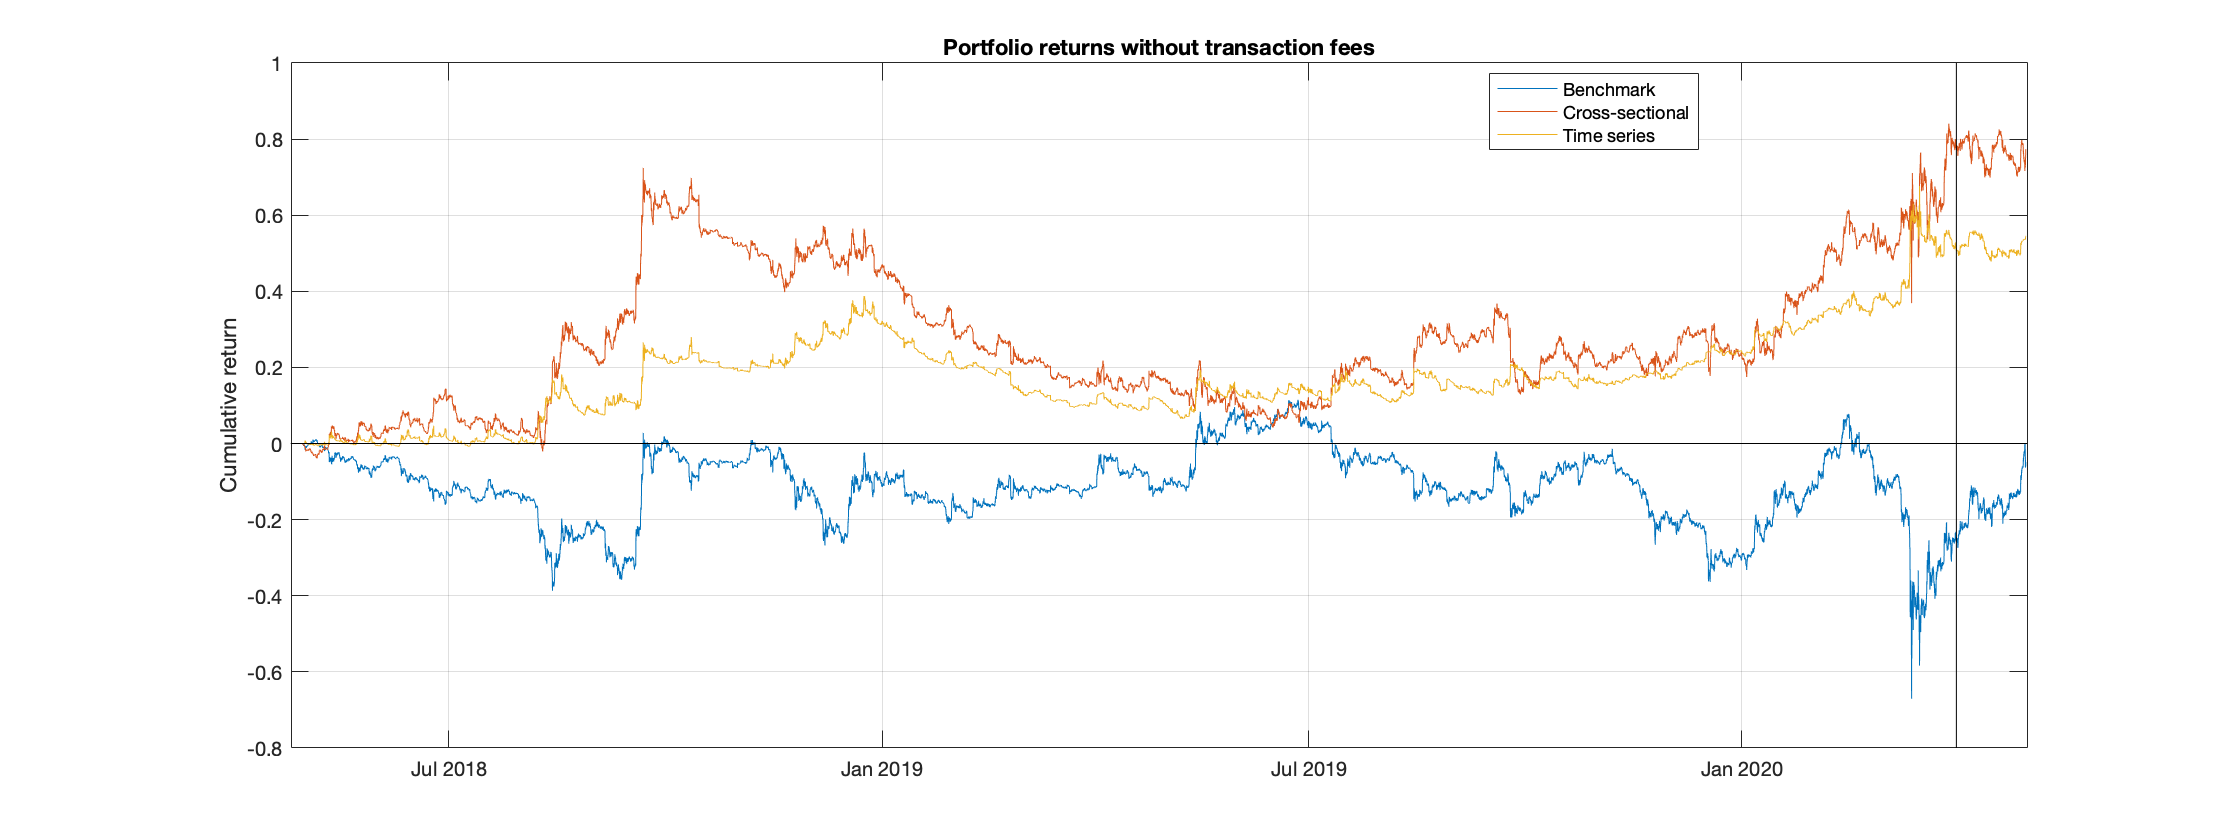

function DD = calculateDD(r)
Px = 100.*(cumprod(1+r)); % PRICE
for j=1:size(r,2)
    for i=1:length(Px)
        if i==1
            c(1,j) = Px(1,j);

            DD(1,j) = 0;
        else
            c(i,j) = max(Px(i,j),c(i-1,j));
            if c(i,j)==Px(i,j)
                DD(i,j)=DD(i-1,j);
            else
                DD(i,j) = 1-Px(i,j)./c(i,j);
            end
        end
    end
end
end

### Performance of strategy

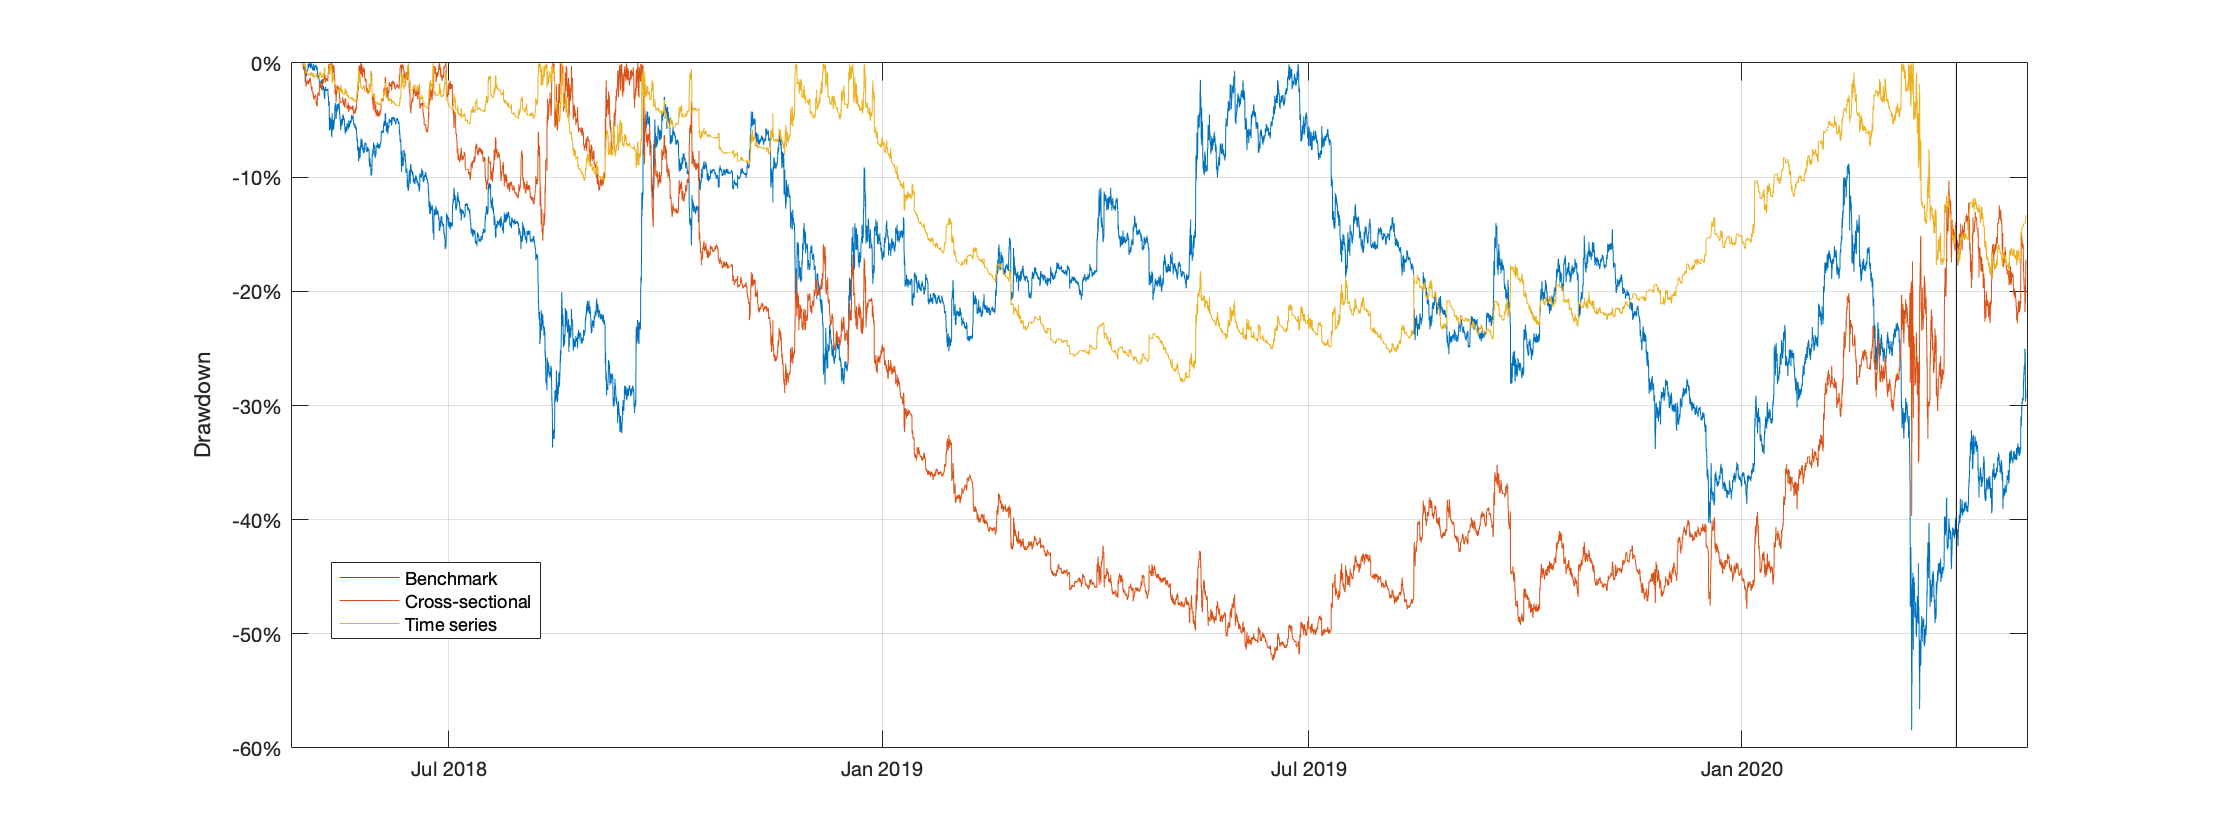

function performanceTable = summaryPerformance(returnTable,riskFreeRate)
    % compute performance metrics
    retns = returnTable{:,:};
    MeanRetn = mean(retns);
    StdRetn = sqrt(var(retns));
    SharpeRatio = (MeanRetn-riskFreeRate)./StdRetn;

    
    cmpRetn = ret2tick(retns, 'method', 'Continuous');
    MaxDD = maxdrawdown(cmpRetn,'geometric');
    TotalRetn = cmpRetn(end, :)-1;

ans = 5×3 table
                   bmTotalRtn     csTotalRtn    tsTotalRtn
                   ___________    __________    __________

    TotalRetn        -0.049318         1.166       0.72374
    SharpeRatio     -0.0077145    0.00078023    -0.0030854
    AverageRetn    -2.8807e-06    4.4022e-05    3.1013e-05
    Volatility       0.0055173     0.0055623     0.0028098
    MaxDrawdown        0.78557       0.68223       0.32239


    perfData = [TotalRetn', SharpeRatio', MeanRetn', StdRetn', MaxDD']';
    
    metricNames = {'TotalRetn', 'SharpeRatio', 'AverageRetn', 'Volatility', 'MaxDrawdown'};
    colStratsNames = (returnTable.Properties.VariableNames)';
    
    
    performanceTable = array2table(perfData, 'VariableNames', colStratsNames, 'RowNames', metricNames);

end